% Design Targets
% #1 Percentage overshoot to a step change in desired angular position = 4.5 %
% #2 Settling time following a step change in desired angular position <= 0.5 sec
% #3 Steady-state error to a step change in desired angular position = 0
% #4 Steady-state error for a unit ramp response = 0.05

% declare s and K
syms s K;

% declare motor/gearbox transfer function
G_m = 500/(s+20);

% H(s) = K * theta(s)/V(s)
H = K * G_m/s; % find the open loop system transfer function

% determine characteristic equation using black's formula
G = simplify(H/(H+1)); % find the closed loop system transfer function
[n,d] = numden(G);
char_eq = d

$$char\_eq = s^{2}+20\,s+500\,K$$

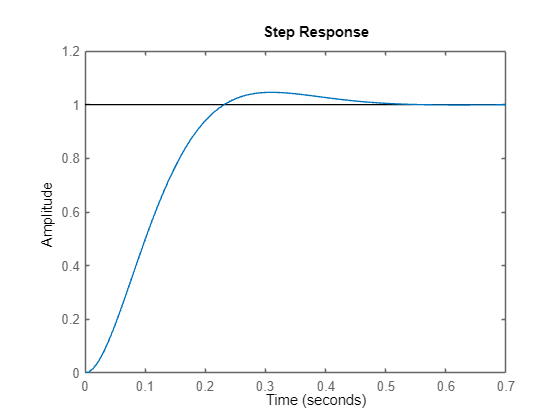

char_eq = collect(expand(char_eq));

% find damping ratio from desired %OS
target_percentage_OS = 4.5; % maximum allowed percentage overshoot
ln2_sc = ((log(target_percentage_OS/100))^2);
damping_ratio = sqrt(ln2_sc/(ln2_sc + pi^2));

% find natural frequency from characteristic equation
% using characteristic equation form s^2 + 2*sigma*s^2 + omega_n^2 = 0 and sigma = zeta*omega_n
char_eq_coeffs = coeffs(char_eq, s, "All"); % get coefficents of powers of s from characteristic equation
damping_coeff = char_eq_coeffs(2)/2;
nat_freq = damping_coeff/damping_ratio;

% find k from natural frequency
eqn = char_eq_coeffs(3)==nat_freq^2;
K_val = solve(eqn, K);

% closed-loop transfer function is now known
n = subs(n, K, K_val);
d = subs(d, K, K_val);
n = collect(expand(n));
d = collect(expand(d));
n_coeffs = double(coeffs(n,s,"All"));
d_coeffs = double(coeffs(d,s,'All'));
G_c = tf(n_coeffs,d_coeffs);
G = subs(G,K,K_val);
H = subs(H,K,K_val);

% calculate steady state error
K_p = limit(H, s, 0, 'right'); % step input
e_ss_step_input = 1/(1+K_p);

K_v = limit(s*H, s, 0); % ramp input
e_ss_ramp_input = double(1/K_v);

% add lag controller
b = 0.01;
syms a;
lag_ctrl = (s+a)/(s+b);
G_lag = lag_ctrl * H;

% calculate new steady state error for ramp input
e_ss_ramp_input_target = 0.05;
K_v_target = 1/e_ss_ramp_input_target;
K_v = limit(s*G_lag, s, 0);
eqn = K_v_target == K_v;
a_val = solve(eqn, a);
lag_ctrl = subs(lag_ctrl, a, double(a_val));
G_lag = expand(subs(G_lag, a, a_val));

% new system with lag_controller is now known
G = simplify(G_lag/(G_lag+1));
[n, d] = numden(G_lag); 
n = collect(expand(n));
d = collect(expand(d));
n_coeffs = double(vpa((coeffs(n,s,'All')/10^30), 20));   % approximate coefficients
d_coeffs = double(vpa((coeffs(d,s,'All')/10^30), 20));
G_ol = tf(n_coeffs, d_coeffs); % open loop continuous transfer function
G_cl = feedback(G_ol, 1);

%               ----------     ---     -----     -----
%       + _    |          |   |   |   |     |   |     |
%  R(s)--|_|---| lag_ctrl |---| K |---| 1/s |---| G_m |-------C(s)
%        -|    |          |   |   |   |     |   |     |   |
%         |     ----------     ---     -----     -----    |
%         |                                               |
%          -----------------------------------------------

% verify system meets requirements
% step input response
step(G_cl); 

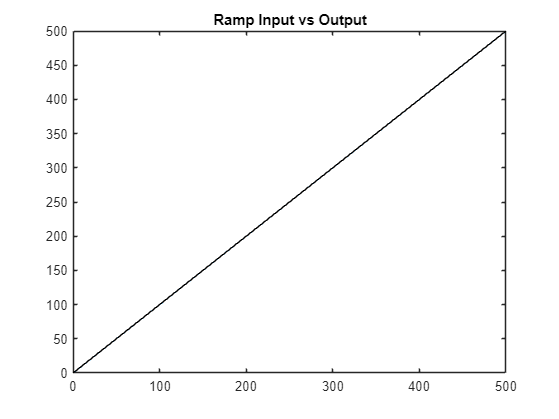

step_info = stepinfo(G_cl);
percentage_OS = step_info.Overshoot;
e_ss_step_input = 1 - dcgain(G_cl);

% ramp input response
t=0:0.001:500;    
ramp_input = t.';
unit_step = zpk([], [0], 1);
G_cl_mod = G_cl*unit_step;
[ramp_response, t1] = step(G_cl_mod, t);
ramp_error = ramp_input - ramp_response;

% plot ramp input results
plot(t, ramp_response);
hold on;
plot(t, ramp_input, "Color", "Black");
title("Ramp Input vs Output");
hold off;

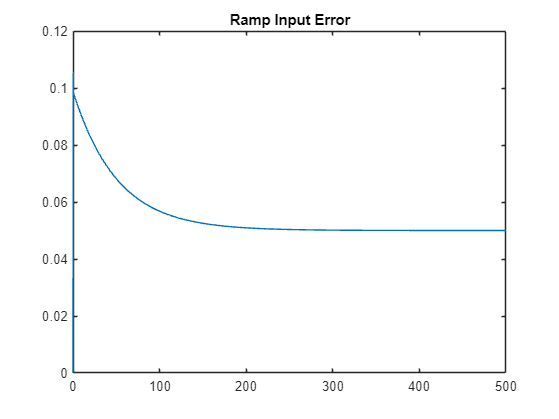

plot(t, ramp_error);
title("Ramp Input Error");

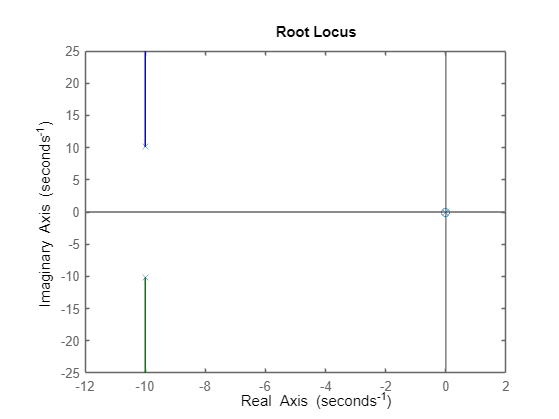


% plot root locus
rlocus(G_cl);